syms('DampRatio')
K=1;
D=0;
num=K;
T1=0.02;
T2=0.002;
den=[T1*T2,T1+T2,1,0];
sys=tf(num,den);
Mpw=1.84;
eq= Mpw==(2*DampRatio*sqrt(1-DampRatio^2))^-1

$$eq = \frac{46}{25}=\frac{1}{2\,\mathrm{DampRatio}\,\sqrt{1-{\mathrm{DampRatio}}^{2}}}$$

eq2= -Mpw==(2*DampRatio*sqrt(1-DampRatio^2))^-1

$$eq2 = -\frac{46}{25}=\frac{1}{2\,\mathrm{DampRatio}\,\sqrt{1-{\mathrm{DampRatio}}^{2}}}$$


s=solve(eq,DampRatio)

$$s = \left(\begin{array}{c} \frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ \frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

s2=solve(eq2,DampRatio)

$$s2 = \left(\begin{array}{c} -\frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ -\frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

ss=[s;s2]

$$ss = \left(\begin{array}{c} \frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ \frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}}\\ -\frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ -\frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

var = vpa(ss)

$$var = \left(\begin{array}{c} 0.959015965051720659303678252829\\ 0.28335204035954443610666490435945\\ -0.959015965051720659303678252829\\ -0.28335204035954443610666490435945 \end{array}\right)$$

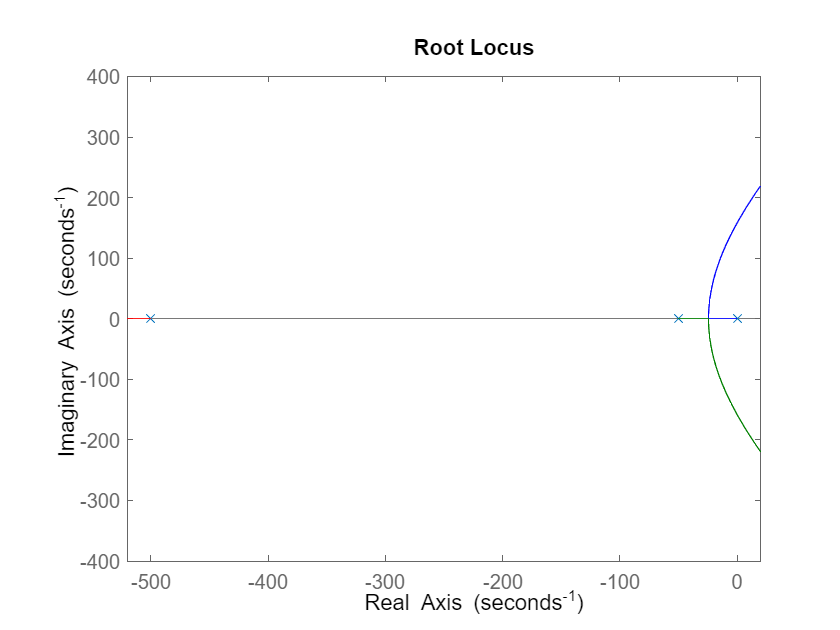

damping_ratio = 0.2834; % check this damping ratio value.
wn = 0:100:400;
rlocus(sys);
axis([-520 20 -400 400])

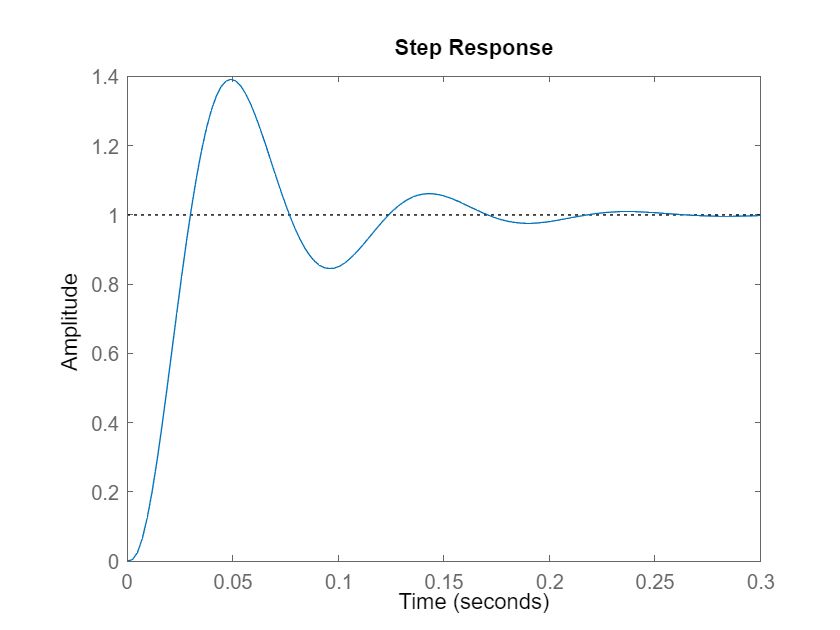

% sgrid(damping_ratio, wn);
% [K, closed_loop_poles] = rlocfind(sys)
% Aready extracted K from rlocfind:
load K.mat


sys2=tf(K,den);
sys_closed=feedback(sys2,1);
step(sys_closed)

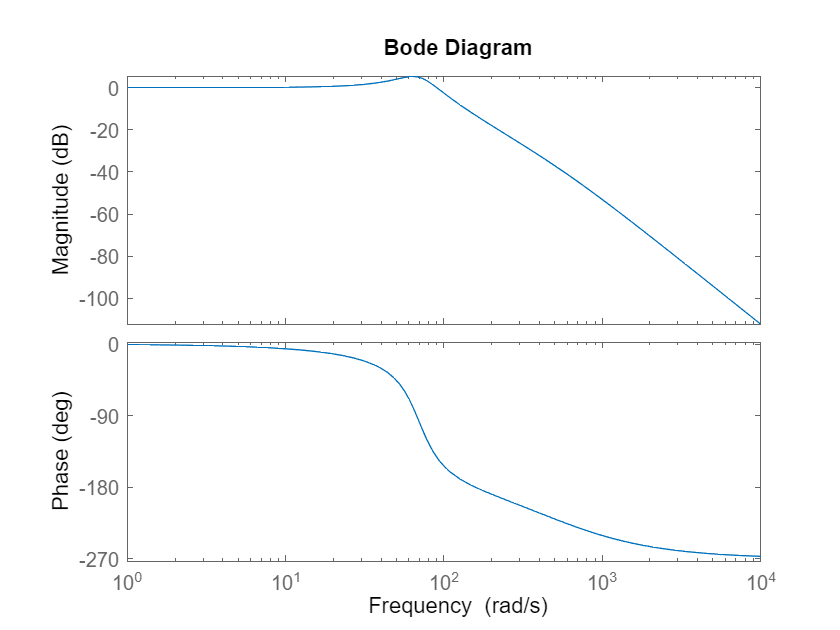

bode(sys_closed)

Solving 20*log(|T|)=5.3 we obtain    ~T=1.84

T=1.84;

